### Repeat the steps for all recordings to make data matrix X

We can now put all the code in one matlab function in "ExtractFeat", and repeat the feature extraction for all recordings. Complete the "ExtractFeat" function. (Note that you won't need to make "VoiceProc.m" in the manual, anymore)

data=[DownM,DownW,LeftM,LeftW,RightM,RightW,UpM,UpW];
num_samples=size(data,2);
num_feat=16;
threshold= 0.1;
Fs = 8000;
L= (20/1000)*8000;
ov= L*0.5;

% matrix for recording the features
X=zeros(num_samples, num_feat);

% Extracting the features
for i=1:size(data,2)
    
    y = data(:,i);
    X(i,:)=ExtractFeat(y,Fs,L,ov,threshold);
    
end

### Labels

The rest of this assignment is repeating the same step as  in module 1. we should now make the Y matrix, the numerical labels are as follows: Down>1, Left>2, Right>3, Up>4. We had 20 recordings for each label, therefore:

Y=[ones(20,1);2.*ones(20,1);3.*ones(20,1);4.*ones(20,1)];

### Train/test split

the code we developed in the first module is now saved as a function "train_test_split" we can use it to split the dat

percent_train_split=70/100;
[train_id,test_id]=train_test_split(Y,percent_train_split);

% splitting the inputs
Xtrain=X(train_id,:);
Xtest=X(test_id,:);

% splitting the labels
Ytrain=Y(train_id,:);
Ytest=Y(test_id,:);

### Standard Normalization

Next we should performing standard normalization on train data and finding the save its mean and standard deviation, use "zscore()" function here.

[Xtrain,mu_train,sigma_train] = zscore(Xtrain);

we should perform any changes we make on training data on the test data too. using the mean and standard deviation of the training data to the test data too

Xtest= (Xtest-mu_train)./sigma_train;

### Feature Selection using mRMR

As before we can use Minimum Redundancy Maximum Relevance (mRMR) for feature extraction.

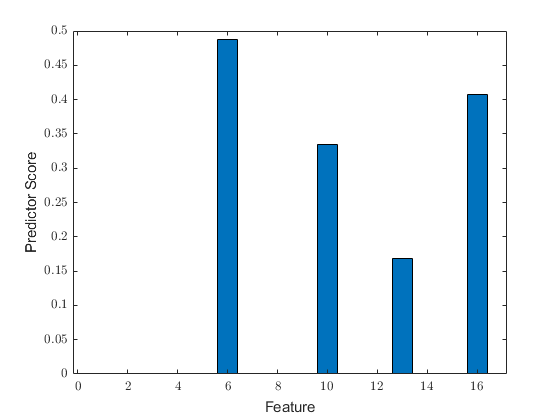

[idx,scores] = fscmrmr(Xtrain,Ytrain);

figure;bar(idx,scores(idx)) %Create bar graph
xlabel('Feature')
set(gca,'TickLabelInterpreter','latex');
ylabel('Predictor Score'); hold off;

you can select the features with higher importance for the rest of this assignment but for now we will just keep all the features.

### Training

As before we use "TreeBagger()"  with different number of trees for the classification model.

rng default
% number of trees
nTrees = 20;

% Train the TreeBagger (Random Forest).
model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');

### Testing the model on test data

Ytest_pred_str = model.predict(Xtest);
Ytest_pred = str2double(Ytest_pred_str);

### Turn the numerical outputs to categorial

num_classes=length(unique(Y))

num_classes = 4

Ytest_cat=zeros(num_classes,size(Ytest,1));
Ytest_pred_cat=zeros(num_classes,size(Ytest,1));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
end

### Plot confusion matrix

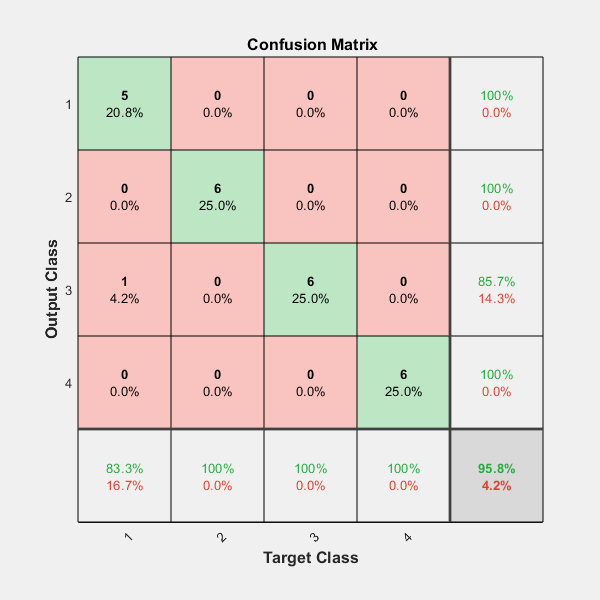

figure; plotconfusion(Ytest_cat,Ytest_pred_cat); hold off;